# EE482 LAB 1

Tylor Cooks, 026538081

Defining given parameters

n = 500; % number of samples
s_ij = [1 .5; -1 1]; % signal projected onto basis function
E1 = 1.25; %Energy signal 1 
E2 = 2;    %Energy power signal 2
data = randi([0,1],[1,n]); %random integer generator between 0-1

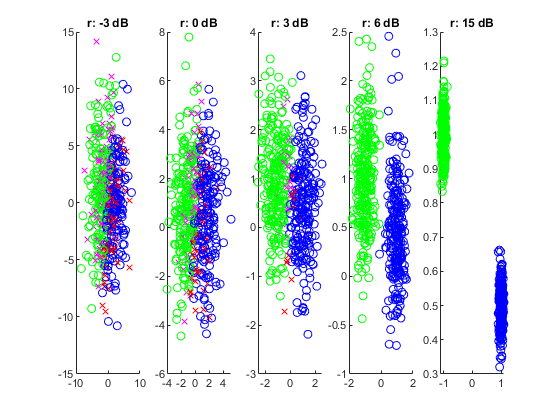

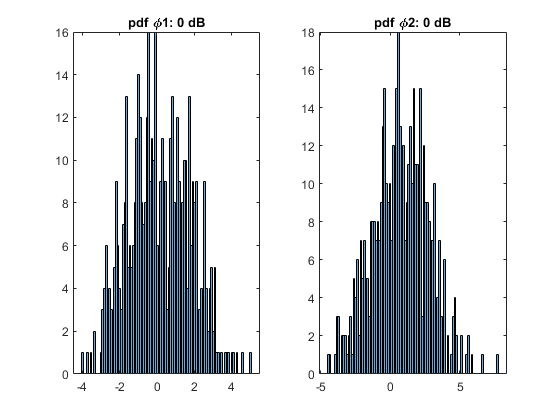

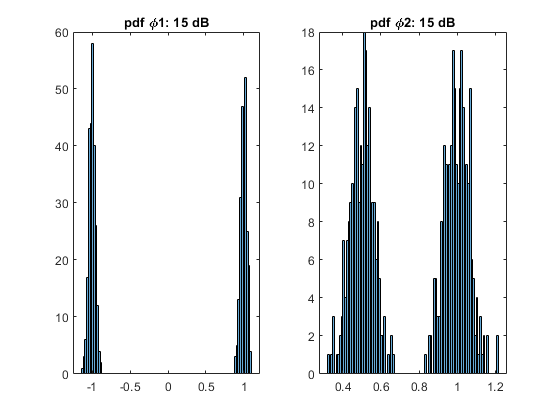

SNRs = [-3 0 3 6 15];
i = 1;
for snr_db = SNRs
    snr = 10^(snr_db/10); % linearizing SNR from db to linear units
    sigma1 = (E1/snr);
    sigma2 = (E2/snr);
    
    % Additive white gaussian noise 
    w1 = normrnd(0,sigma1,1,n);
    w2 = normrnd(0,sigma2,1,n);
 
    r11 = (s_ij(1,1)+ w1);
    r12 = (s_ij(1,2)+ w2);
    r21 = (s_ij(2,1)+ w1); 
    r22 = (s_ij(2,2)+ w2);
    
    %if the intended signal is 1, use this
    d1 = (r21 - s_ij(1,1)).^2 + (r22 - s_ij(1,2)).^2 >=...
         (r21 - s_ij(2,1)).^2 + (r22 - s_ij(2,2)).^2;
     
    %if the intended signal is 0, use this
    d0 = (r11 - s_ij(1,1)).^2 + (r12 - s_ij(1,2)).^2 >=...
         (r11 - s_ij(2,1)).^2 + (r12 - s_ij(2,2)).^2;
    
    
    r = zeros(2,n);
    figure(1)
    subplot(1,5,i)
    
% Part 1 [Decision Boundary & Decision Region]
    for v = 1:n
      if data(v) == 1
        r(1,v) = (r21(v));
        r(2,v) = (r22(v));
        if d1(v) == data(v)
            scatter(r21(v),r22(v),'g','DisplayName','1-R correct')
        else
            scatter(r21(v),r22(v),'xr','DisplayName','1-R error')
        end
      else  
        r(1,v) = (r11(v));
        r(2,v) = (r12(v));
        if d0(v) == data(v)
            scatter(r11(v),r12(v),'b','DisplayName','0-R Correct')
        else 
            scatter(r11(v),r12(v),'xm','DisplayName','0-R error')
        end
      end
      hold on
    end
    if snr_db == 0
    %leg = legend('1-R correct','1-R error','0-R Correct','0-R error');
    end
    title(['r: ', num2str(SNRs(i)), ' dB']);
    hold off
    
% Part 2 [Probability Density Function (pdf) of the generated samples]
% for SNR 0 and 15
    if snr_db == 0
        figure(2)
        subplot(1,2,1)
        histogram(r(1,:),100)
        title(['pdf \phi1: ', num2str(SNRs(i)), ' dB']);
        
        subplot(1,2,2)
        histogram(r(2,:),100)
        title(['pdf \phi2: ', num2str(SNRs(i)), ' dB']);
    end

    if snr_db == 15
        figure(3)
        subplot(1,2,1)
        histogram(r(1,:),100)
        title(['pdf \phi1: ', num2str(SNRs(i)), ' dB']);
        
        subplot(1,2,2)
        histogram(r(2,:),100)
        title(['pdf \phi2: ', num2str(SNRs(i)), ' dB']);
    end
    
    
    
    i = i+1;
end

**Part 3 [Discussion]**

    This project was an exercise of an optimum reciever. For the analysis of part 1, was an exercise of the optimum receiver for binary data transmission. First, we projected the signals given onto the orthonormal basis functions. I believe this is significant because we are representing the signals in a signal space which makes it easier to derive the boundry decision rule, in this case. The next step for part 1 was to get the energy of the two signals, which was used to calculate the SNR given the  additive white gaussian noise (AWGN). As expected the recieved signals started to cluster correctly the higher the SNR, having a few to zero errors at 6 dB and no errors at 15 dB.

***green = 1 recieved, correct***

***red = 1 recieved, incorrect***

***blue = 0 recieved, correct***

***magenta = 0 recieved, incorrect***

    For part 2, probability density funciton for recieved data at 0 dB and 15 dB, the plotting of the random variables, r1 and r2, followed expected behaviors. Interesting observation is when the SNR = 0 dB, the pdf follows a bell curve representative of the pdf of the AWGN. Where the SNR 15, the pdfs are centered around the projections onto the basis functions.

**Conclusion**

Although the lab works as expected ,  I could've improved the code by calculating the recieved data individually and storing them in a vector. However, the lab results were as expected. The only question would be when calculating the SNR value there seemed to be confusion on what formula to use, whether the sigma to square the sigma or to divide the signal energy by the number of data points to get the average. Other than that this was a very informative lab on the optimum reciever. 